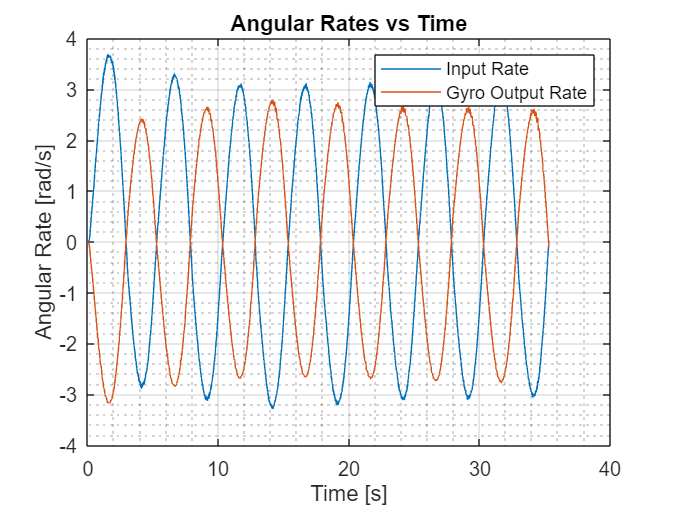

clc; clear

% Load Data
data = load('2023_10_13_002_RWHEEL_05_02');
time = data(:,1); %[s]
gyro_output = data(:,2); %[rad/s]
input = data(:,3); %[rpm]

% Adjust Time Vector
time = time - 13523.26;
time(1) = 0;

% Convert rpm -> rad/s
input = input./60; %[rps]
input = input * 2*pi;

% Plot vs Time
figure();
plot(time,input)
hold on
plot(time,gyro_output)
hold off
grid on;grid minor
xlabel('Time [s]')
ylabel('Angular Rate [rad/s]')
legend('Input Rate','Gyro Output Rate')
title('Angular Rates vs Time')


% Plot Input vs Output
figure();
scatter(input,gyro_output,'.')
hold on
xlabel('Input Rate [rad/s]')
ylabel('Output Rate [rad/s]')
title('Gyro Data')
grid on; grid minor

% Determine K
p = polyfit(input,gyro_output,1);
K = p(1).*input + p(2);
p(1)

ans = -0.8586

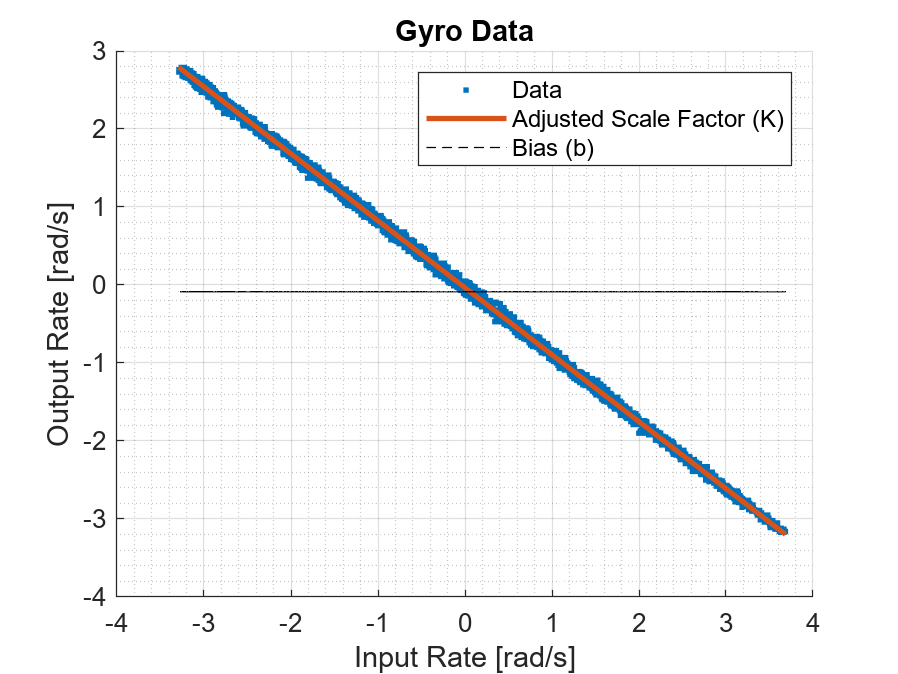


% Plot K
plot(input,K,'LineWidth',2)

% Detrmine b
b = mean(gyro_output);
b = b + zeros(length(input),1);

% Plot b
plot(input,b,'--k')
legend('Data','Adjusted Scale Factor (K)','Bias (b)')
hold off

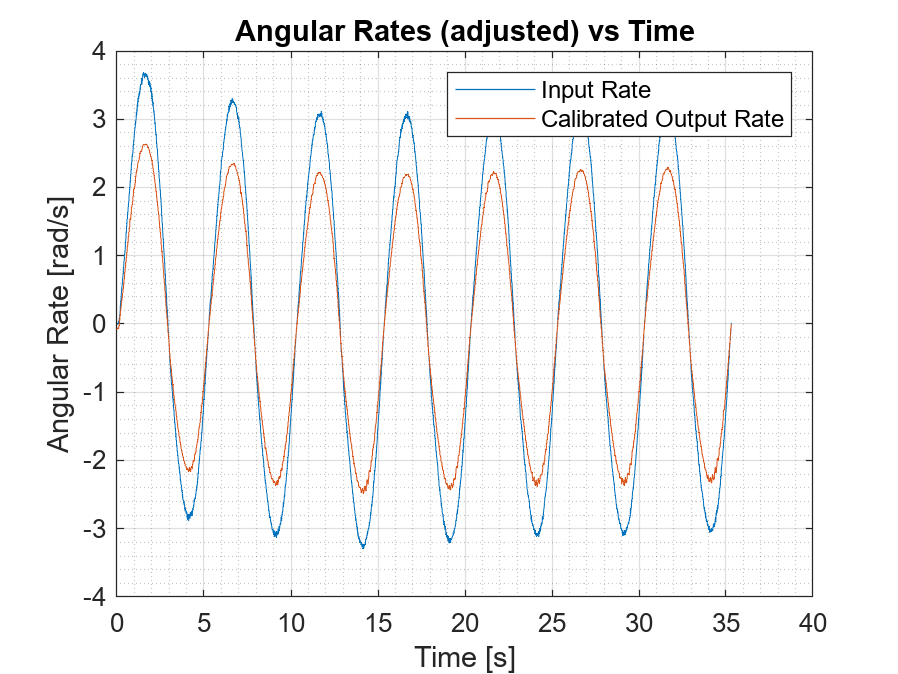


% Adjust Gyro Measurements
adj_gyro = p(1)*gyro_output + b;

% Plot New vs Time
figure();
plot(time,input)
hold on
plot(time,adj_gyro)
legend('Input Rate','Calibrated Output Rate')
hold off
grid on; grid minor
xlabel('Time [s]')
ylabel('Angular Rate [rad/s]')
title('Angular Rates (adjusted) vs Time')

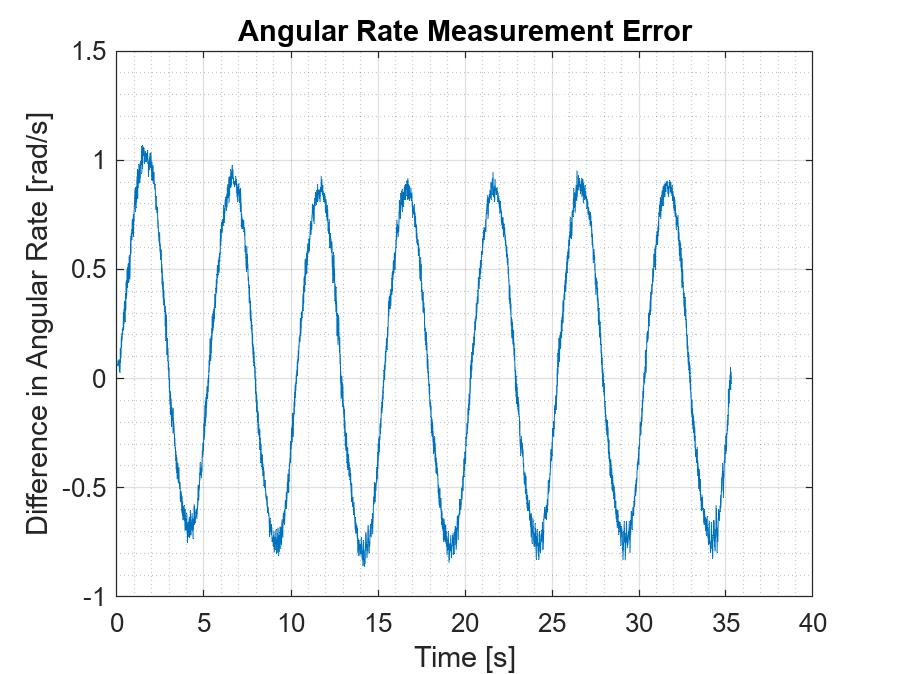


% Find and Plot Differences - Rate
difference_rate = input - adj_gyro;

figure();
plot(time,difference_rate)
title('Angular Rate Measurement Error')
xlabel('Time [s]')
ylabel('Difference in Angular Rate [rad/s]')
grid on; grid minor;

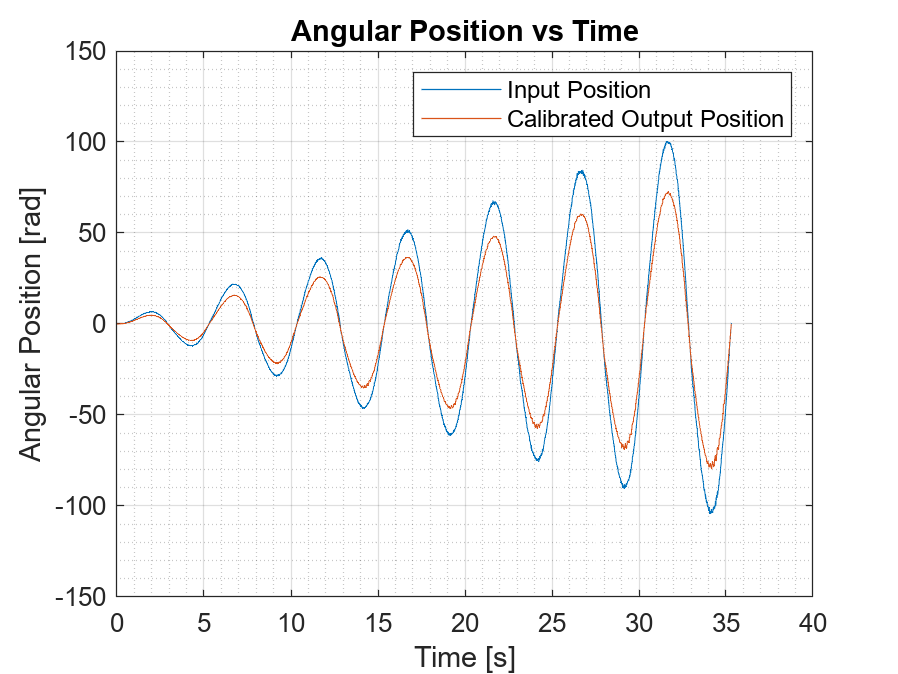


% Find and Plot Angular Position
input_pos = input .* time;
adj_gyro_pos = adj_gyro .* time;

figure();
plot(time,input_pos)
hold on
plot(time,adj_gyro_pos)
hold off
grid on; grid minor
title('Angular Position vs Time')
ylabel('Angular Position [rad]')
xlabel('Time [s]')
legend('Input Position','Calibrated Output Position')

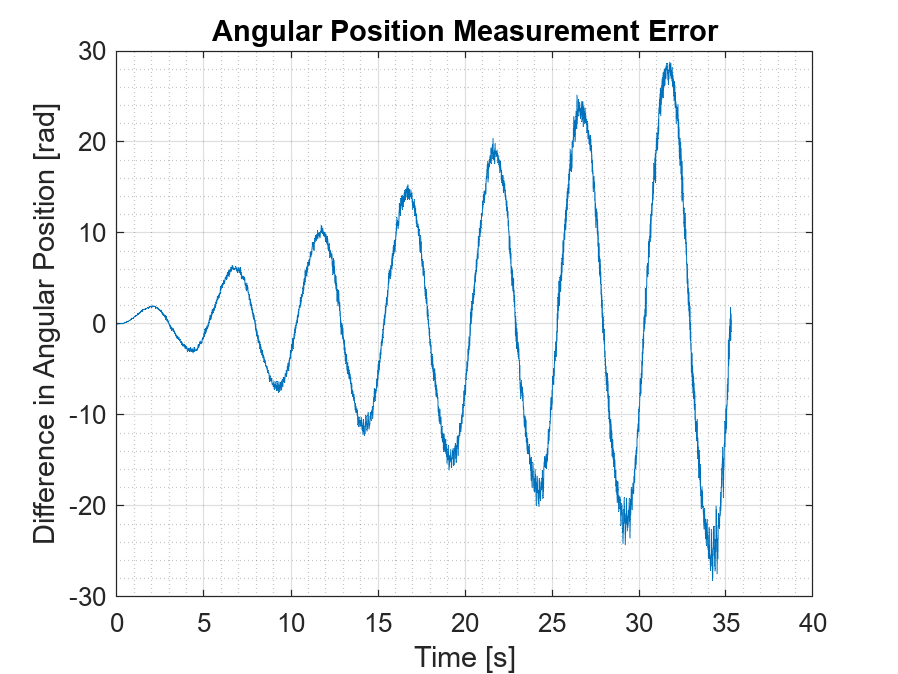


% Find and Plot Differences - Position
difference_pos = input_pos - adj_gyro_pos;

figure();
plot(time,difference_pos)
title('Angular Position Measurement Error')
xlabel('Time [s]')
ylabel('Difference in Angular Position [rad]')
grid on; grid minor

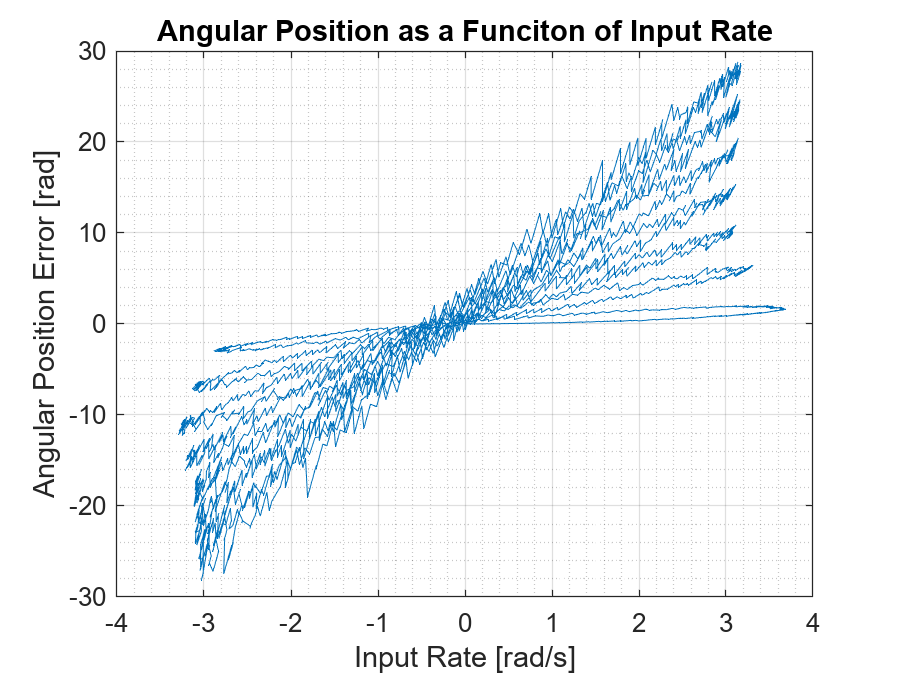


% Angular Position as a Funciton of Input Rate
figure();
plot(input,difference_pos)
grid on; grid minor
title('Angular Position as a Funciton of Input Rate')
xlabel('Input Rate [rad/s]')
ylabel('Angular Position Error [rad]')